# Readback and Analysis

## I. Read all the datastream

clear; clc;

% Get the directory path:
dirpath="G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback"

dirpath = "G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback"

**Read all filepath:**

% Read file paths
filepaths = get_filepaths(dirpath);

    {["G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M1_a.csv" ]}    {["G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M1_b.csv" ]}    {0×0 double                                                                                }    {0×0 double                                                                               }    {0×0 double                                                                               }
    {["G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M2_a.csv" ]}    {["G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M2_b.csv" ]}    {["G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M2_c.csv" ]}    {0×0 double                                                                               }    {0×0 double                                                                               }
    {["G:\My Drive\BME\8. félév\Szakdolgoz

% Create a structured measurement-data matrix
data_matrix = process_bulk_data_matrix(filepaths);

G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M1_a.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M1_b.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M2_a.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M2_b.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M2_c.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M3_a.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M3_b.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M3_c.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M4_a.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M4_b.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluation\records_for_readback\M4_c.csv
G:\My Drive\BME\8. félév\Szakdolgozat\matlab\Evaluatio

## II. Plots

### a. cursor position

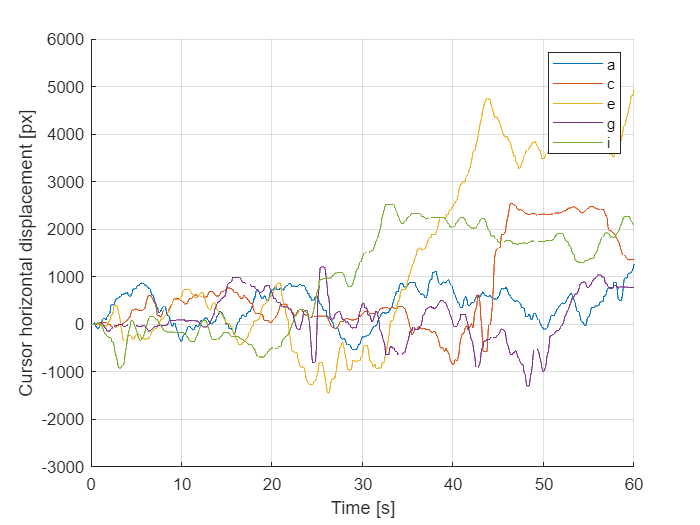

%1
s_plot(get_u(data_matrix,{"M1_a","M3_a","M5_a","M7_a", "M9_a"}),60,{'a', 'c', 'e', 'g', 'i'},"", "Time [s]", "Cursor horizontal displacement [px]", [-3000,6000]);

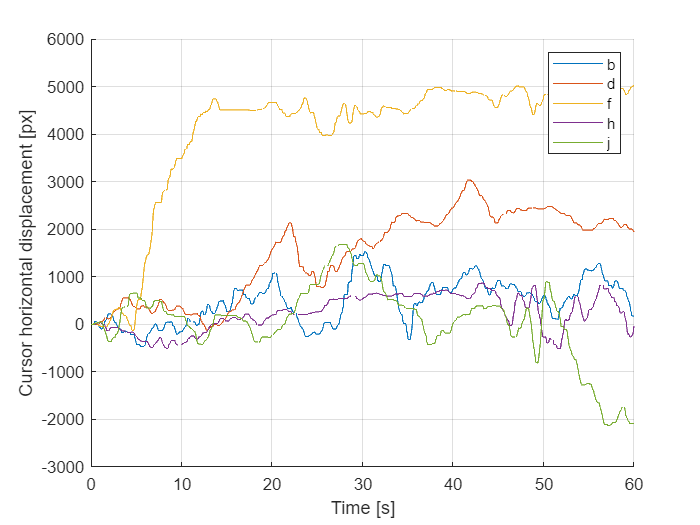

%2
s_plot(get_u(data_matrix,{"M2_a","M4_a","M6_a","M8_a","M10_a"}),60,{'b', 'd', 'f', 'h', 'j'},"", "Time [s]", "Cursor horizontal displacement [px]", [-3000,6000]);

### b.I. cursor velocity

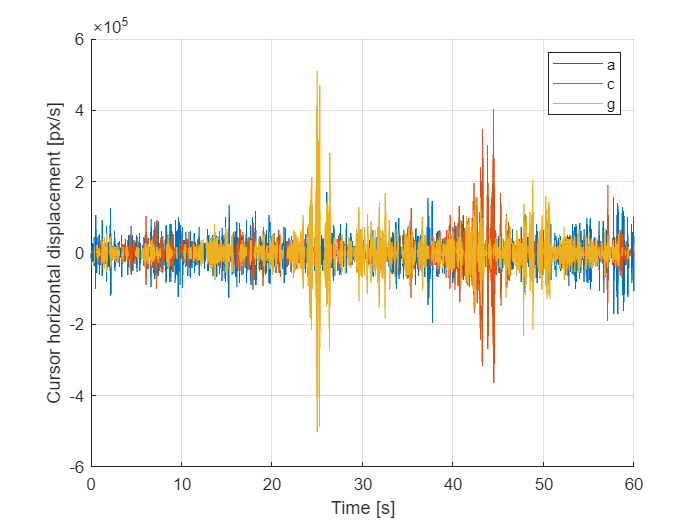

%3
s_plot(get_du(data_matrix,{"M1_a","M3_a","M7_a"}),60,{'a', 'c', 'g'},"", "Time [s]", "Cursor horizontal displacement [px/s]", [-600000,600000]);

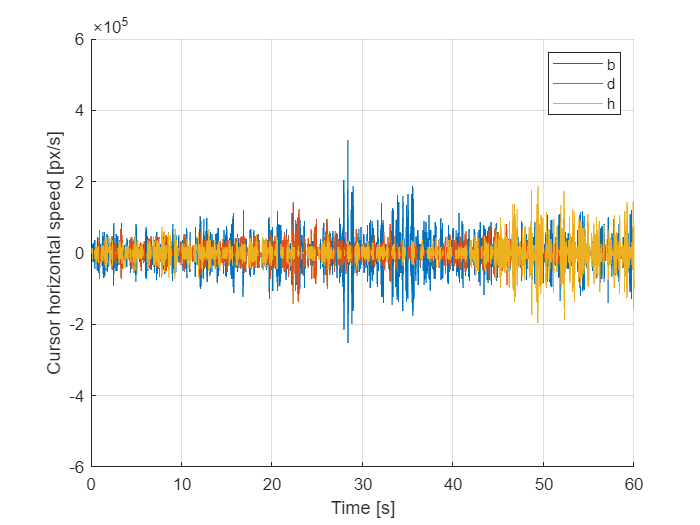

%4
s_plot(get_du(data_matrix,{"M2_a","M4_a","M8_a"}),60,{'b', 'd', 'h'},"", "Time [s]", "Cursor horizontal speed [px/s]", [-600000,600000]);

### b.II. cursor velocity vs time delay

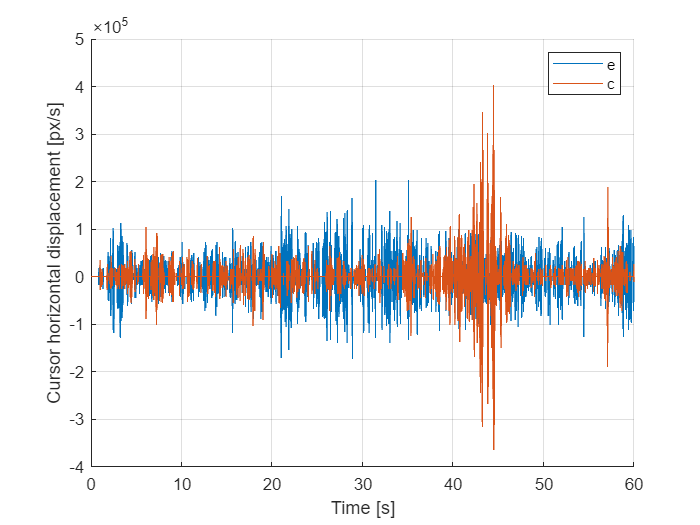

%5
s_plot(get_du(data_matrix,{"M5_a","M3_a"}),60,{'e', 'c'},"", "Time [s]", "Cursor horizontal displacement [px/s]", [-400000,500000]);

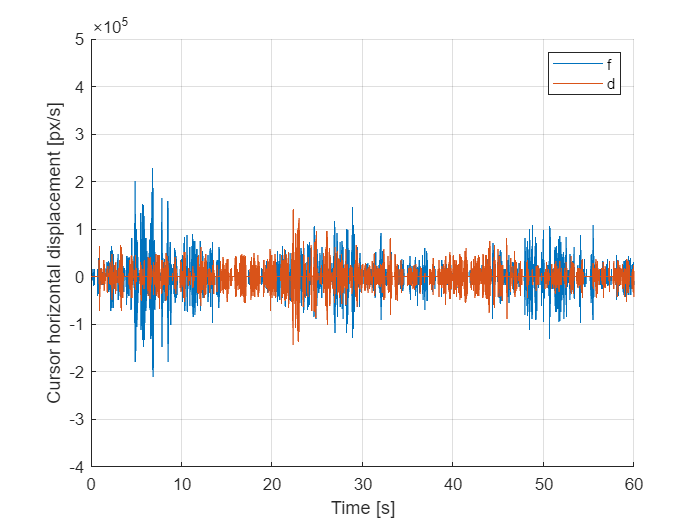

%6
s_plot(get_du(data_matrix,{"M6_a","M4_a"}),60,{'f', 'd'},"", "Time [s]", "Cursor horizontal displacement [px/s]", [-400000,500000]);

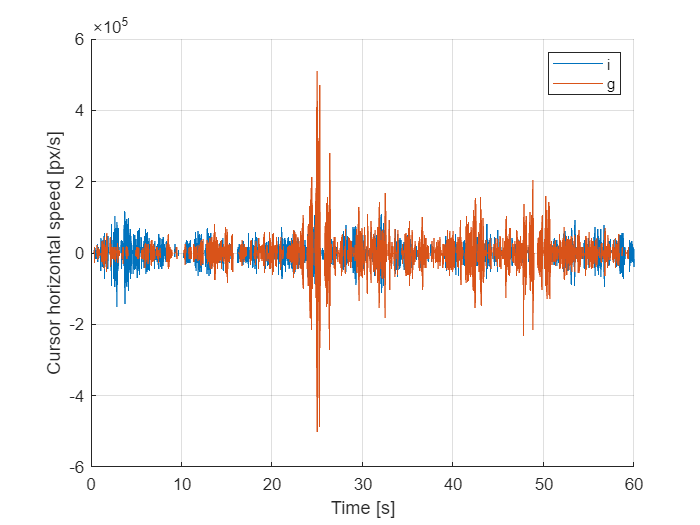

%7
s_plot(get_du(data_matrix,{ "M9_a","M7_a"}),60,{'i', 'g'},"", "Time [s]", "Cursor horizontal speed [px/s]", [-600000,600000]);

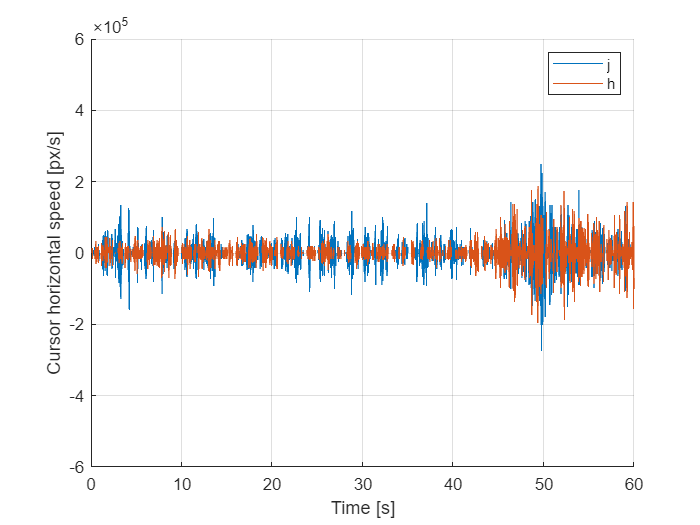

%8
s_plot(get_du(data_matrix,{"M10_a","M8_a"}),60,{'j', 'h'},"", "Time [s]", "Cursor horizontal speed [px/s]", [-600000,600000]);

### c. cursor acceleration

%s_plot(get_ddu(data_matrix,{"M1_a","M3_a","M5_a","M7_a", "M9_a"}),60,{'Dataset 1', 'Dataset 3', 'Dataset 5', 'Dataset 7', 'Dataset 9'},"PlotTitle");
%s_plot(get_ddu(data_matrix,{"M2_a","M4_a","M6_a","M8_a","M10_a"}),60,{'Dataset 1', 'Dataset 3', 'Dataset 5', 'Dataset 7', 'Dataset 9'},"PlotTitle");

### d.I. rod angle error

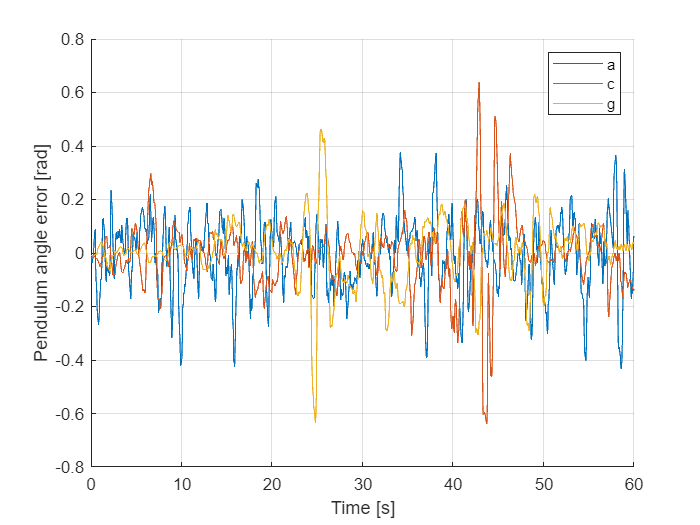

%9
s_plot(get_phi1_err(data_matrix,{"M1_a","M3_a","M7_a"}),60,{'a', 'c', 'g'},"", "Time [s]", "Pendulum angle error [rad]", [-0.8,0.8]);

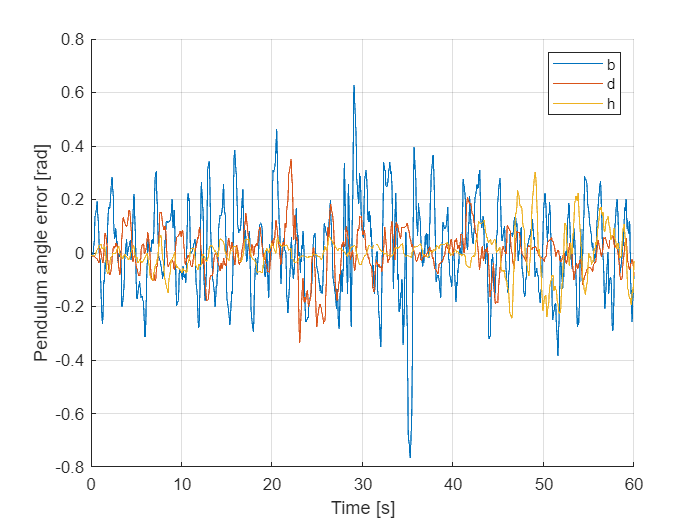

%10
s_plot(get_phi1_err(data_matrix,{"M2_a","M4_a","M8_a"}),60,{'b', 'd', 'h'},"", "Time [s]", "Pendulum angle error [rad]", [-0.8,0.8]);

### d.II. rod angle error vs time delay

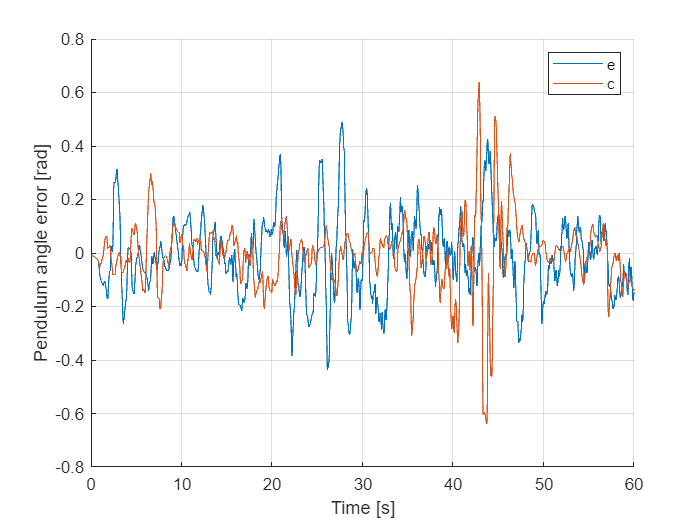

%11

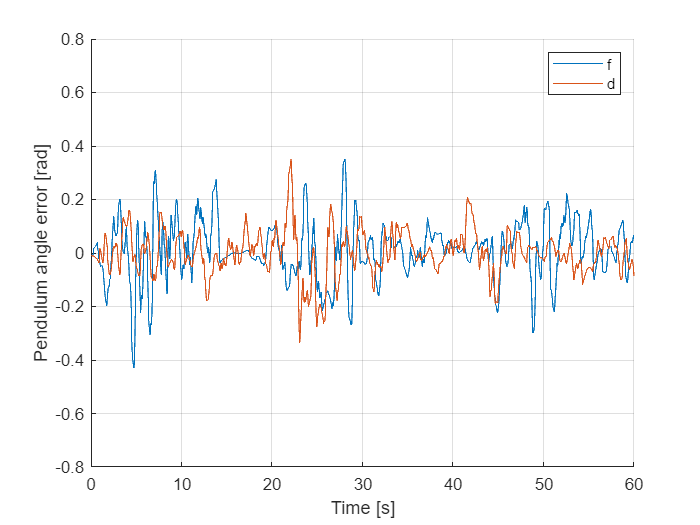

s_plot(get_phi1_err(data_matrix,{"M5_a","M3_a"}),60,{'e', 'c'},"", "Time [s]", "Pendulum angle error [rad]", [-0.8,0.8]);
%12
s_plot(get_phi1_err(data_matrix,{"M6_a","M4_a"}),60,{'f', 'd'},"", "Time [s]", "Pendulum angle error [rad]", [-0.8,0.8]);

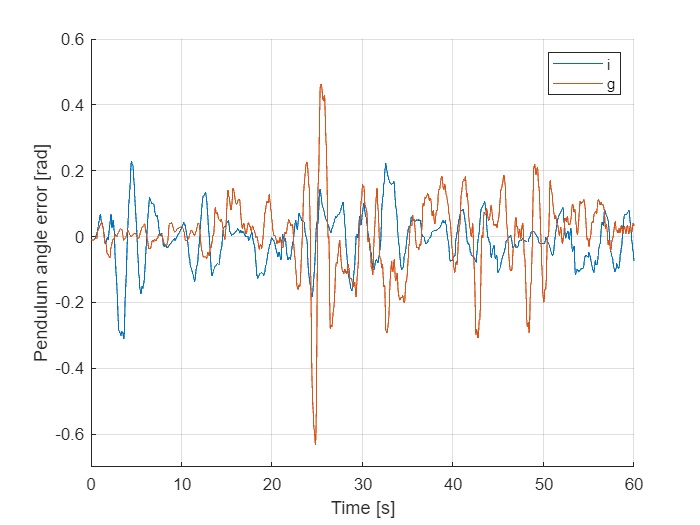

%13
s_plot(get_phi1_err(data_matrix,{ "M9_a","M7_a"}),60,{'i', 'g'},"", "Time [s]", "Pendulum angle error [rad]", [-0.7,0.6]);

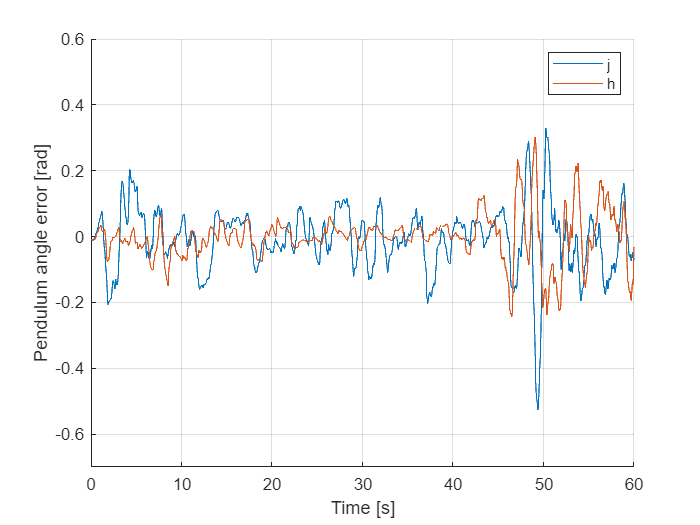

%14
s_plot(get_phi1_err(data_matrix,{"M10_a","M8_a"}),60,{'j', 'h'},"", "Time [s]", "Pendulum angle error [rad]", [-0.7,0.6]);

### e.I. rod angular velocity

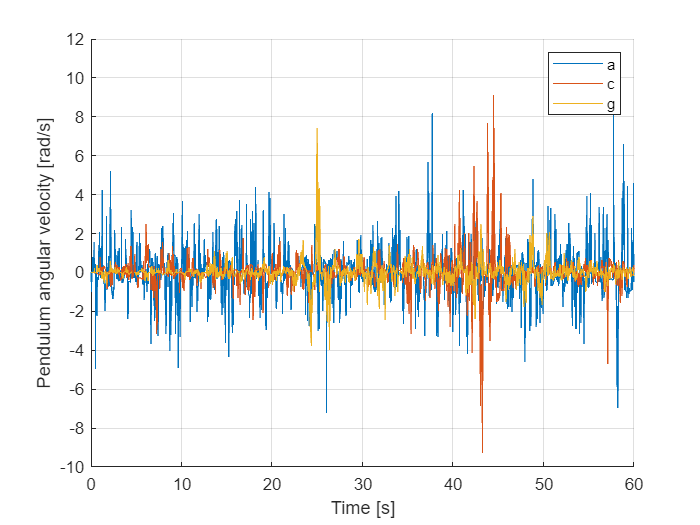

%15
s_plot(get_dphi1(data_matrix,{"M1_a","M3_a","M7_a"}),60,{'a', 'c', 'g'},"", "Time [s]", "Pendulum angular velocity [rad/s]", [-10,12]);

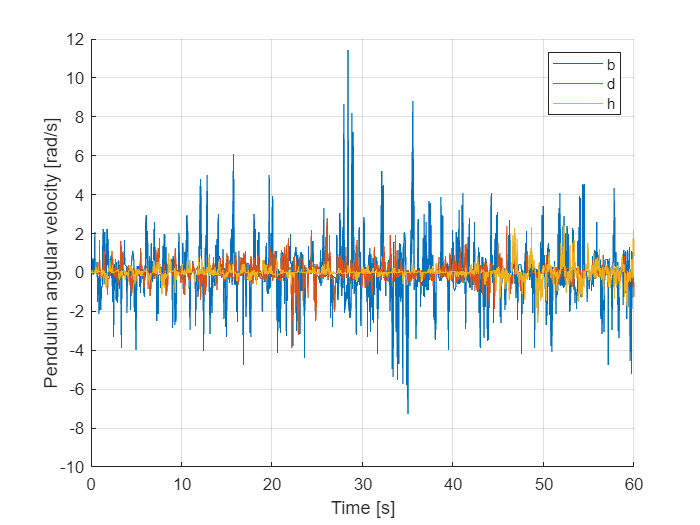

%16
s_plot(get_dphi1(data_matrix,{"M2_a","M4_a","M8_a"}),60,{'b', 'd', 'h'},"", "Time [s]", "Pendulum angular velocity [rad/s]", [-10,12]);

### e.II. rod angular velocity vs time delay

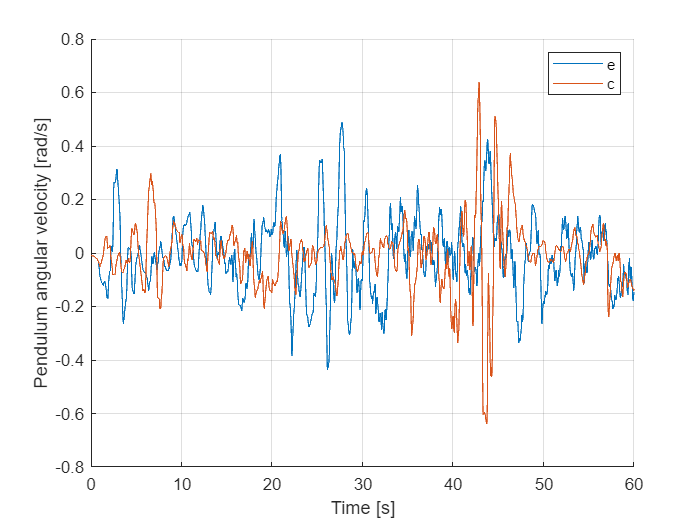

%17
s_plot(get_phi1_err(data_matrix,{"M5_a","M3_a"}),60,{'e', 'c'},"", "Time [s]", "Pendulum angular velocity [rad/s]", [-0.8,0.8]);

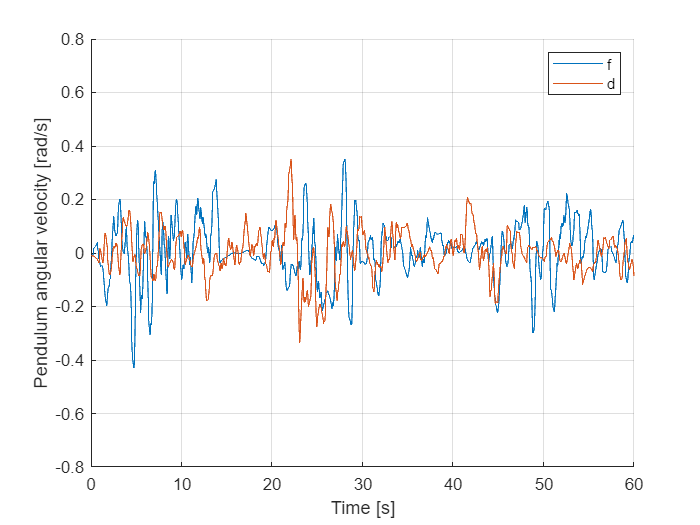

%18
s_plot(get_phi1_err(data_matrix,{"M6_a","M4_a"}),60,{'f', 'd'},"", "Time [s]", "Pendulum angular velocity [rad/s]", [-0.8,0.8]);

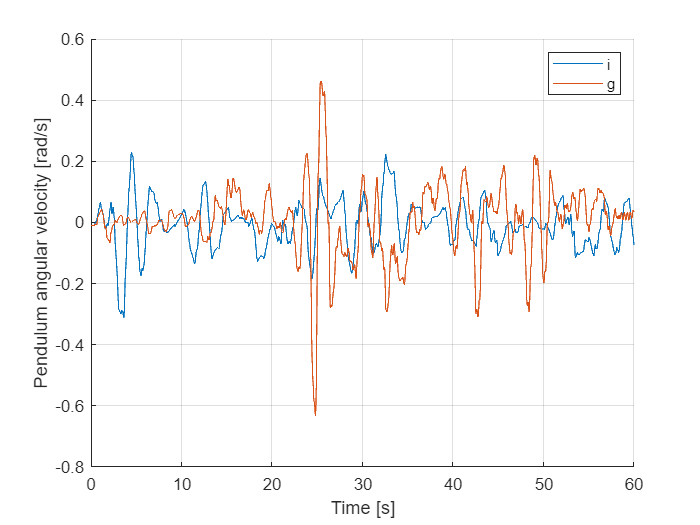

%19
s_plot(get_phi1_err(data_matrix,{ "M9_a","M7_a"}),60,{'i', 'g'},"", "Time [s]", "Pendulum angular velocity [rad/s]", [-0.8,0.6]);

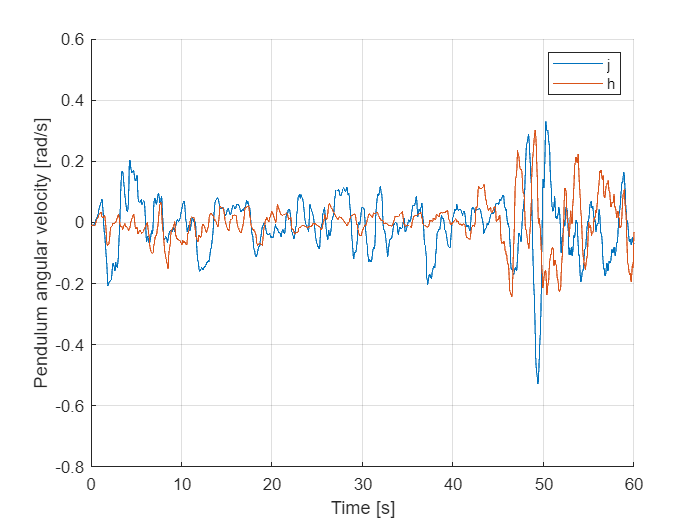

%20
s_plot(get_phi1_err(data_matrix,{"M10_a","M8_a"}),60,{'j', 'h'},"", "Time [s]", "Pendulum angular velocity [rad/s]", [-0.8,0.6]);

## III. Analysis

Datafield variables for visible and invisible second rod cases:

datafield_u_v = get_u(data_matrix,{"M1_a","M3_a","M5_a","M7_a","M9_a"});
datafield_u_i = get_u(data_matrix,{"M2_a","M4_a","M6_a","M8_a","M10_a"});
datafield_du_v = get_du(data_matrix,{"M1_a","M3_a","M5_a","M7_a","M9_a"});
datafield_du_i = get_du(data_matrix,{"M2_a","M4_a","M6_a","M8_a","M10_a"});
datafield_ddu_v = get_ddu(data_matrix,{"M1_a","M3_a","M5_a","M7_a","M9_a"});
datafield_ddu_i = get_ddu(data_matrix,{"M2_a","M4_a","M6_a","M8_a","M10_a"});
datafield_phi1_v = get_phi1_err(data_matrix,{"M1_a","M3_a","M5_a","M7_a","M9_a"});
datafield_phi1_i = get_phi1_err(data_matrix,{"M2_a","M4_a","M6_a","M8_a","M10_a"});
datafield_dphi1_v = get_dphi1(data_matrix,{"M1_a","M3_a","M5_a","M7_a","M9_a"});
datafield_dphi1_i = get_dphi1(data_matrix,{"M2_a","M4_a","M6_a","M8_a","M10_a"});

### III.1. Statistical sheets

**b. cursor velocity**

analyze_datafield_linvel(datafield_du_v,{"a","c","e","g","i"})

ans = 5×3 table
         Standard Deviation of Speed (m/s)    RMS Speed (m/s)    Speed Energy (m)
         _________________________________    _______________    ________________

    a               4.8026e+06                  4.8024e+06          2.7319e+08   
    c               4.8279e+06                  4.8276e+06          1.8813e+08   
    e               8.0101e+06                  8.0094e+06          2.8657e+08   
    g               6.1095e+06                   6.109e+06          2.1666e+08   
    i               3.6134e+06                  3.6132e+06          1.5757e+08   


analyze_datafield_linvel(datafield_du_i,{"b","d","f","h","j"})

ans = 5×3 table
         Standard Deviation of Speed (m/s)    RMS Speed (m/s)    Speed Energy (m)
         _________________________________    _______________    ________________

    b               6.0701e+06                  6.0697e+06          2.4046e+08   
    d               2.9973e+06                  2.9971e+06          1.4509e+08   
    f                4.787e+06                  4.7866e+06          1.7917e+08   
    h               4.1941e+06                  4.1938e+06          1.7001e+08   
    j               4.5187e+06                  4.5184e+06           1.852e+08   


calculateStatisticsTableLinvel(datafield_du_i,datafield_du_v,{"b","d","f","h","j"})

ans = 5×6 table
         Standard Deviation of Speed (m/s) - DataCell1    Standard Deviation of Speed (m/s) - DataCell2    RMS Speed (m/s) - DataCell1    RMS Speed (m/s) - DataCell2    Speed Energy (m) - DataCell1    Speed Energy (m) - DataCell2
         _____________________________________________    _____________________________________________    ___________________________    ___________________________    ____________________________    ____________________________

    b                     6.0701e+06                                       4.8026e+06                              6.0697e+06                     4.8024e+06                      2.4046e+08                      2.7319e+08         
    d                     2.9973e+06                   

**d. rod angle error**

analyze_datafield_angle(datafield_phi1_v,{"a","c","e","g","i"})

ans = 5×3 table
         Standard Deviation (rad)    RMS (rad)    Trapz Integral (rad*s)
         ________________________    _________    ______________________

    a             0.16044             0.16073             10.259        
    c             0.11626             0.11649             6.0855        
    e             0.19301             0.19345             8.5329        
    g             0.11037             0.11038             5.2431        
    i            0.084131            0.085344             4.4217        


analyze_datafield_angle(datafield_phi1_i,{"b","d","f","h","j"})

ans = 5×3 table
         Standard Deviation (rad)    RMS (rad)    Trapz Integral (rad*s)
         ________________________    _________    ______________________

    b             0.20267             0.20326             10.064        
    d            0.075991            0.075996             4.4191        
    f             0.14614             0.14613             6.1436        
    h            0.075144            0.075269             3.8757        
    j            0.096216            0.096713             5.3302        


calculateStatisticsTableAngle(datafield_phi1_v,datafield_phi1_i,{"b","d","f","h","j"})

ans = 5×6 table
         Standard Deviation (rad) - DataCell1    Standard Deviation (rad) - DataCell2    RMS (rad) - DataCell1    RMS (rad) - DataCell2    Trapz Integral (rad*s) - DataCell1    Trapz Integral (rad*s) - DataCell2
         ____________________________________    ____________________________________    _____________________    _____________________    __________________________________    __________________________________

    b                   0.16044                                 0.20267                         0.16073                  0.20326                         10.259                                10.064              
    d                   0.11626                                0.075991                         0.11649      

**e. rod angle error**

analyze_datafield_angle(datafield_dphi1_v,{"a","c","e","g","i"})

ans = 5×3 table
         Standard Deviation (rad)    RMS (rad)    Trapz Integral (rad*s)
         ________________________    _________    ______________________

    a             1.0475               1.0475             65.651        
    c            0.64053              0.64049             27.678        
    e            0.89491              0.89539             37.805        
    g            0.45475              0.45473              17.85        
    i            0.26066              0.26076             12.182        


analyze_datafield_angle(datafield_dphi1_i,{"b","d","f","h","j"})

ans = 5×3 table
         Standard Deviation (rad)    RMS (rad)    Trapz Integral (rad*s)
         ________________________    _________    ______________________

    b             1.3326               1.3327              60.54        
    d            0.39089              0.39087             20.502        
    f            0.69944               0.6999             27.948        
    h            0.31421              0.31419             13.777        
    j             0.3453              0.34535             17.744        


calculateStatisticsTableAngle(datafield_dphi1_v,datafield_dphi1_i,{"a, b","c, d","e, f","g, h","i, j"})

ans = 5×6 table
            Standard Deviation (rad) - DataCell1    Standard Deviation (rad) - DataCell2    RMS (rad) - DataCell1    RMS (rad) - DataCell2    Trapz Integral (rad*s) - DataCell1    Trapz Integral (rad*s) - DataCell2
            ____________________________________    ____________________________________    _____________________    _____________________    __________________________________    __________________________________

    a, b                   1.0475                                  1.3326                           1.0475                   1.3327                         65.651                                 60.54              
    c, d                  0.64053                                 0.39089                          0

### III.2. Frequency spectrums

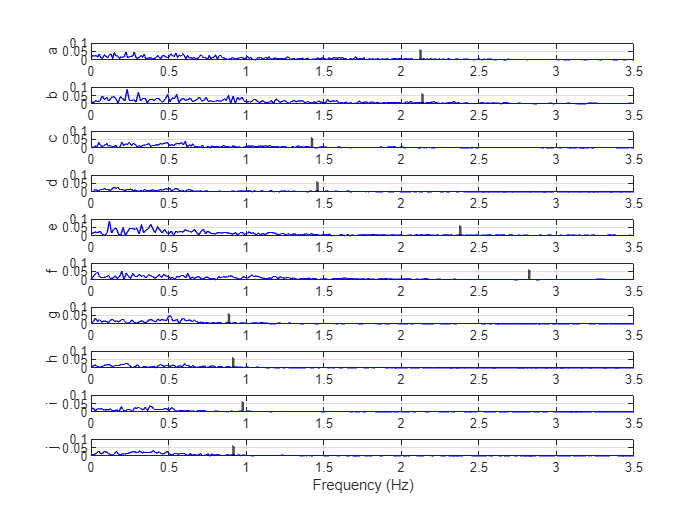

%plotFrequencySpectrum(datafield_phi1_v,{"a","c","e","g","i"})
%plotFrequencySpectrum(datafield_phi1_i,{"b","d","f","h","j"})
freq95_vals = plotFrequencySpectrum(interleaveDataCells(datafield_phi1_v,datafield_phi1_i),{"a","b","c","d","e","f","g","h","i","j"},[0,0.1]);

disp(freq95_vals);

    2.1243    2.1364    1.4248    1.4604    2.3801    2.8240    0.8899    0.9166    0.9788    0.9178

